# DeepAction Example Script: Creating a New Project

This example covers the basics of creating a new DeepAction project. Specifically, we run users through an example project covering steps 1-5 on the toolbox workflow (shown below).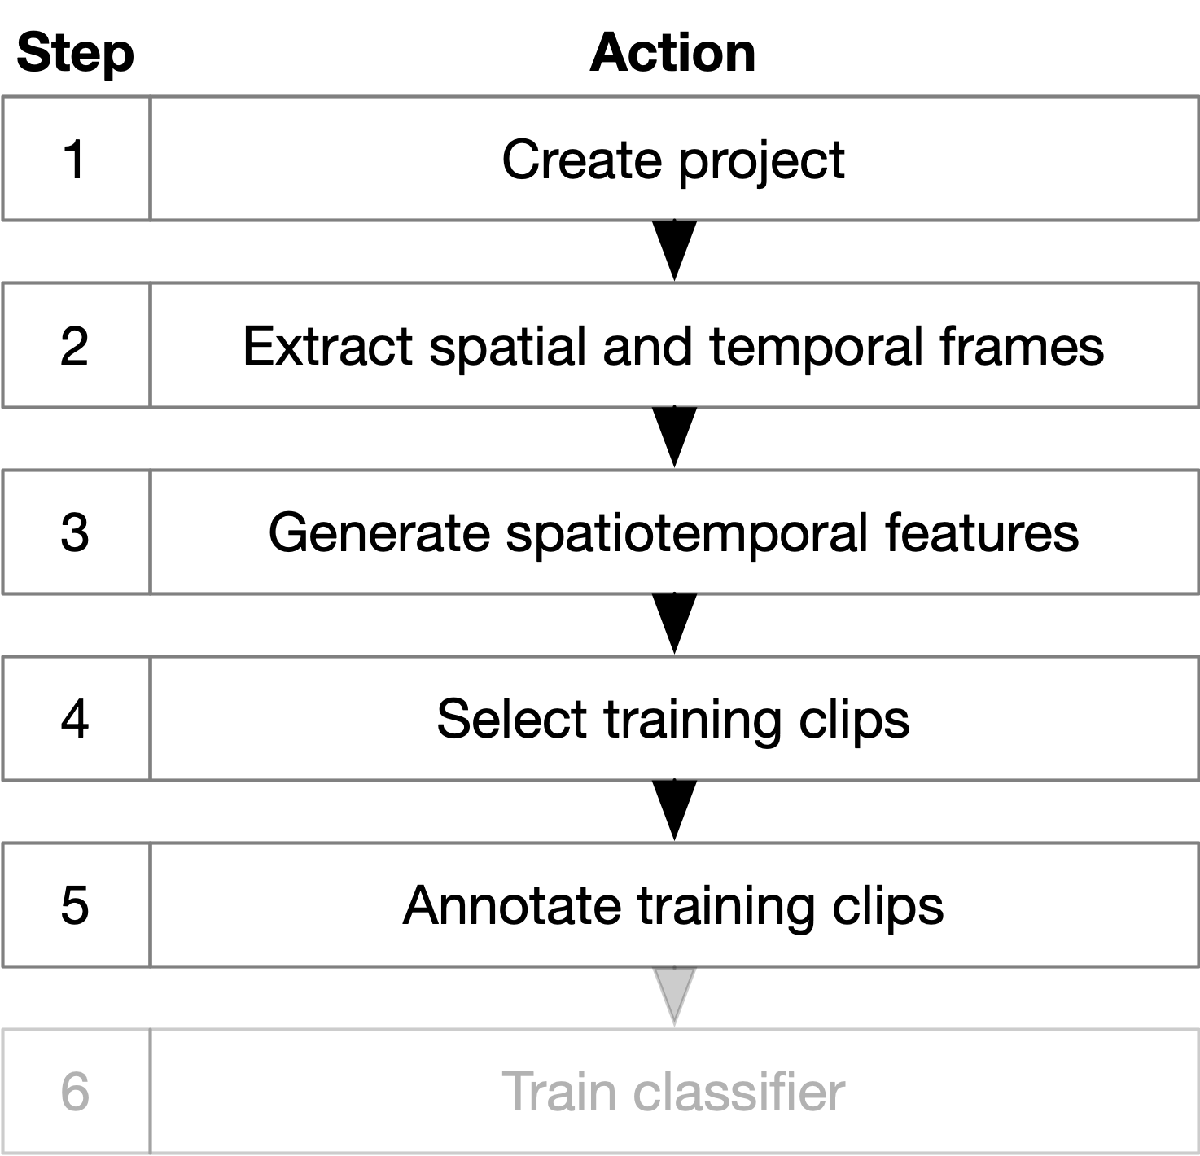

## Setting up the toolbox

The only step required to set up the toolbox is adding the toolbox to your MATLAB path. To do so, change the variable $\texttt{toolbox\_path}$ below to the location of the toolbox on your system (here, I assume the toolbox is located in the present working directory). The command $\texttt{savepath}
$ saves the current search path so the toolbox doesn't need to be added to the path each time a new MATLAB instance is opened. Comment it out if this is not desirable.

toolbox_path = pwd;
addpath(genpath(toolbox_path))
savepath;

## Downloading the demonstration data

Next, download the demonstration project(s) if you have not done so already. Here, we'll be importing data from $\texttt{./Example Datasets/demo\_data}$, so you only need to download the $\texttt{demo\_data}$ folder to run this example. The demonstration data for the examples is included via Google Drive link [here](https://drive.google.com/drive/folders/1jE6OKFNRZqhdqCmZ_--5uEfTUMBtxRnF?usp=sharing).

## Creating the project

Next, we define an instance of our DeepAction project by specifying the path to the project folder. When we create a new project, DeepAction will create the specified folder and initialize a configuration file $$\texttt{config.txt}$$. Here, for example, if we want to create a project named $$\texttt{DeepActionDemo}$$, the path to our project folder is

projectName = 'project_1'
projectFolder = fullfile('/Users/harriscaw/Documents/Behavior classification/Projects', projectName)

We then initialize a DeepActionProject using the specified folder projectFolder as follows:

project = DeepActionProject(projectFolder);

Then, to create the project, we simply run the $$\texttt{CreateProject()}$$method, which creates the project folder and populates it with a configuration file.  

project.CreateProject()

The configuration file, $$\texttt{config.txt}$$, contains the project parameters and is used to run the pipeline. Detailed for the configuration file can be found in $$\texttt{Config.md}$$. In this example, we will highlight the relevant parameters for steps 1-5 of the DeepAction workflow.

## Importing videos

After creating an empty project, we need to import the videos we'd like to label. To do so, we run the $$\texttt{ImportVideos}$$ method on our DeepAction project with a table of the names and paths to the videos we'd like to add. 

Here, we use the example dataset provided. We define the names and paths to the videos as follows:

videoFolder = '/Users/harriscaw/Documents/Behavior classification/Example datasets/project_1_videos' % Path to folder containing videos
VideoName = {'20080324115556', '20080324143707A', '20080324143707B', '20080421153635', '20080422170445'}';
VideoPath = fullfile(videoFolder, strcat(VideoName, '.mp4'));

We then store the video names and paths as a table:

importTable = table(VideoName, VideoPath)
disp(importTable)

Now, we import the video into the project by calling the $$\texttt{ImportVideos}$$ method. This method copies all the videos specified by $$\texttt{importTable.VideoPath}$$ into the project's $$\texttt{./videos}$$ folder, with names specified by $$\texttt{importTable.VideoName}$$. It also initializes as set of empty annotations for each video in the $$\texttt{./annotations}$$ folder. 

project.ImportVideos(importTable)

## Generating spatial and temporal frames

We then generate the spatial and temporal frames for the project (step 2). To do so, we first specify the format with which to store the extracted frame data. In the configuration file, we do this via the $$\texttt{ImageType}$
$ parameter. Here we have three options:

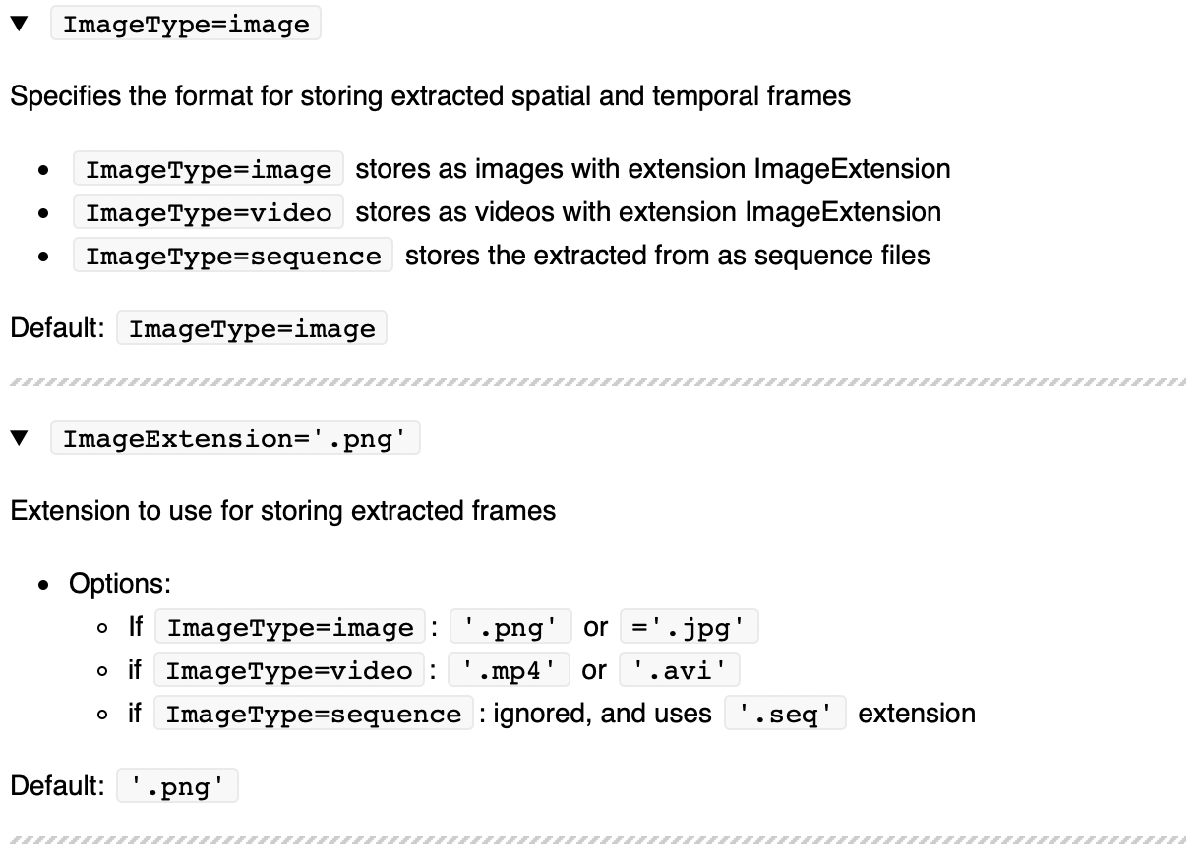

By default, frames are stores as $$\texttt{.png}$
$ images. 

We then extract the spatial and temporal frames using the $$\texttt{GenerateFrames}$
$method. By default, both spatial and temporal frames are extracted. To extract only the spatial stream, specify $$\texttt{TemporalStream=false}$$ in the configuration file. 

There are a number of options for extracting the temporal stream, which can be computaitonally intensive. They are:

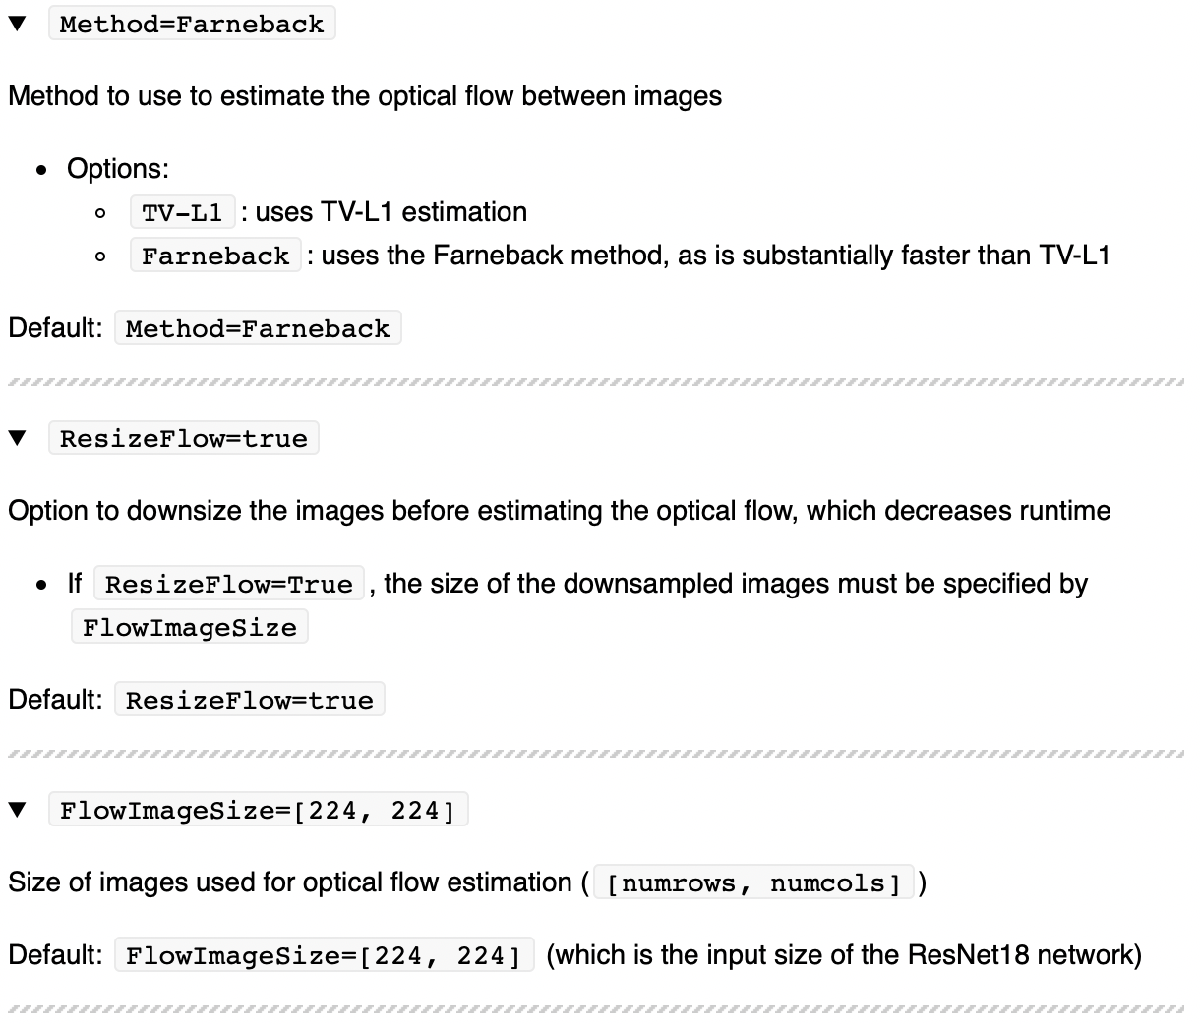

After specifing the desired parameters, we run the $$\texttt{GenerateFrames}$
$method, which extracts frames from all the videos in the project. If the method is interrupted, videos for which all frames have already been extracted will be skipped.

There is an additional option to parallelize the $$\texttt{GenerateFrames}$$ method, which is often faster if sufficient computational resources are available. To do so, specify the parameter $$\texttt{Parallelize}$$ as $$\texttt{true}$$ when running the generate frames command (i.e., $$\texttt{project.GenerateFrames('Parallelize', true)}$$). By default, the method is not parallelized. 

project.GenerateFrames();

## Extracting CNN features

After generating the spatial (and if desired, temporal) frames, we extract features using pretrained convolutional neural networks (CNN) via the $$\texttt{ExtractFeatures}$$ method. The relevant configuration file parameters are described below:

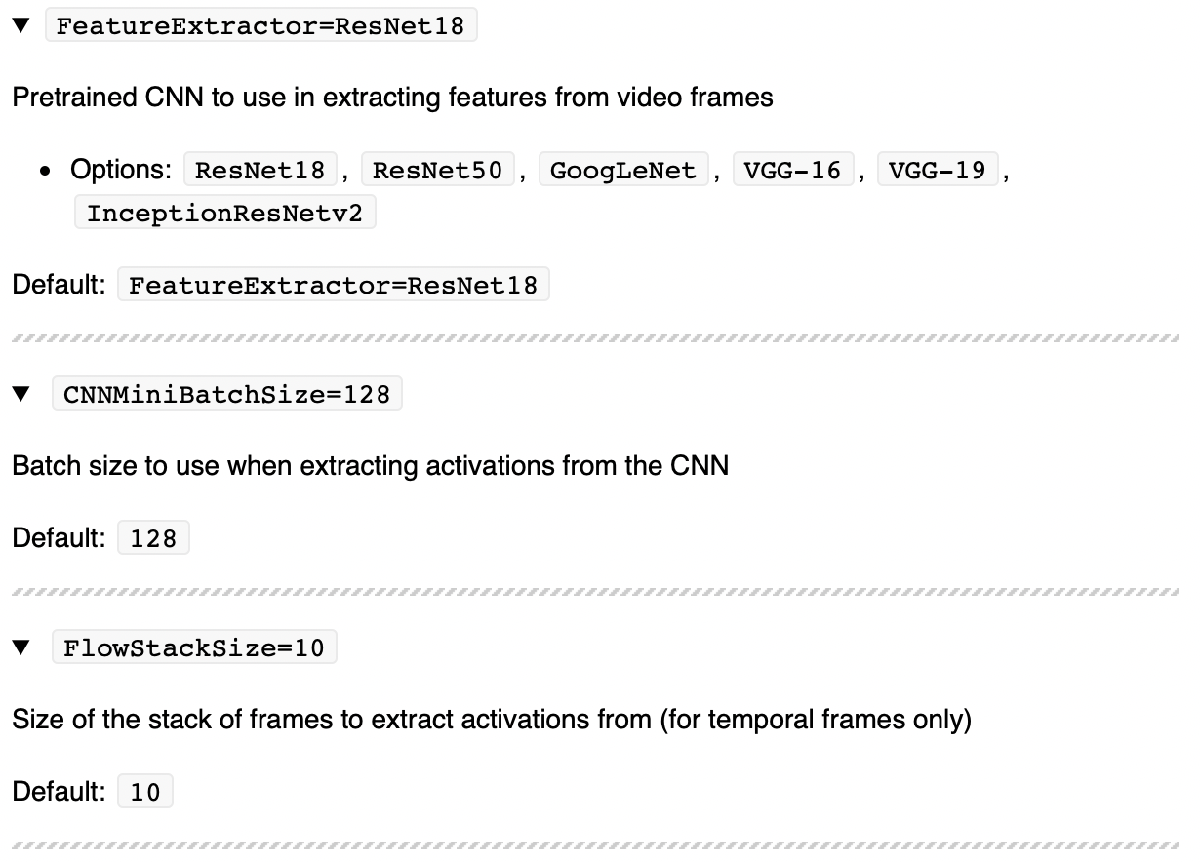

As with frame generation, we again have the option to parallelize this process. To do so, specify $$\texttt{project.ExtractFeatures('Parallelize', true)$. By default the method does not use parallelization.

project.ExtractFeatures();

## Reducing feature dimensionality

After spatial and temporal features have been extracted from video frames, there is an option to reduce the size of the input features to the classifier via dimensionality reduction. This is useful for decreasing training time and memory usage, and we have found it is significantly improved classifier performance. In this example we use reconstruction independent component analysis (RICA) to create reduce the dimensionality of the features from 1024 to 512. 

The method GenerateRICAModel is used to create a RICA model object, which is stored in the ./rica_models subfolder of the project folder. After the model is generated, it can be reused, so this process only needs to be completed once (for a given set of input streams and reduced dimensionality). The parameters used in generating the RICA model are as follows:

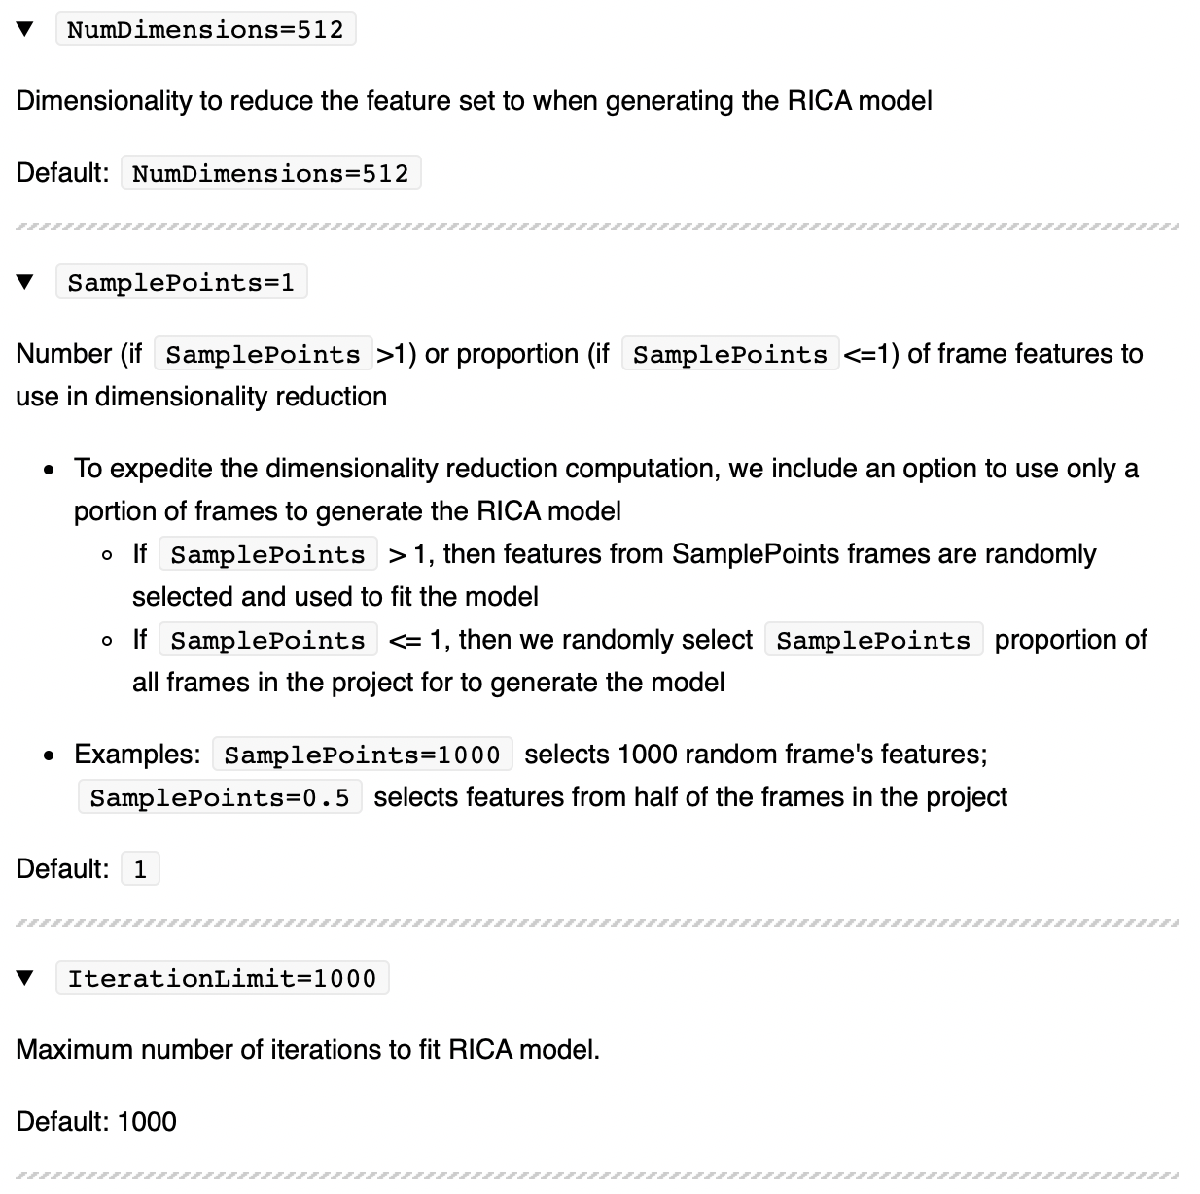

project.GenerateRICAModel()

Next, we define using the set of behaviors of interest in our project using the *Behavior Table Application *included in this toolbox. In addition to the names of the behaviors, we also require uses provide a keyboard key corresponding to that behavior of interest. This will be used in the manual annotation app to denote the start/stop of behaviors by keypress. Behaviors can be added and deleted via the corresponding buttons. Behavior labels and keys can be edited by clicking on the corresponding cells.

BehaviorTable(project)

## Manual annotation of training data

After features have been extracted, we select frames to manually label for use in training the classifier. To do so, we divide each video into short clips and then select a random subset of those clips to annotate. To relevant parameter for dividing the project videos into clips is $\texttt{ClipLength}$ in the configuration file.

project = project.GetAnnotatorData()

We can then annotate the clips using the annotator. 

project = project.LaunchAnnotator(); 

## Recap

In this segment we demonstrated the process for creating a project, generating spatial and temporal frames and features, and launching the manual annotator. 